PM调制的软件实现

待处理信号

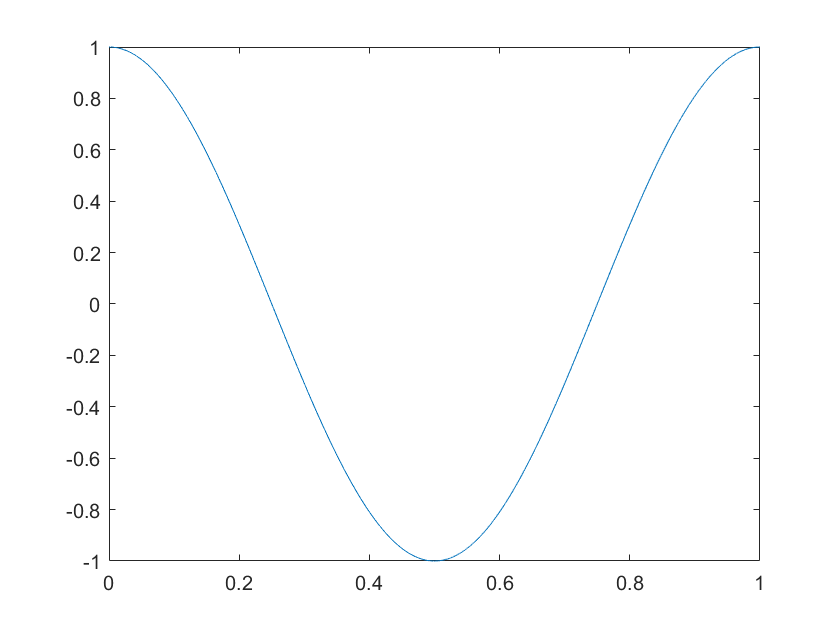

fs = 10000;
t = 0:1/fs:1;
message = cos(2*pi*t);
plot(t, message);

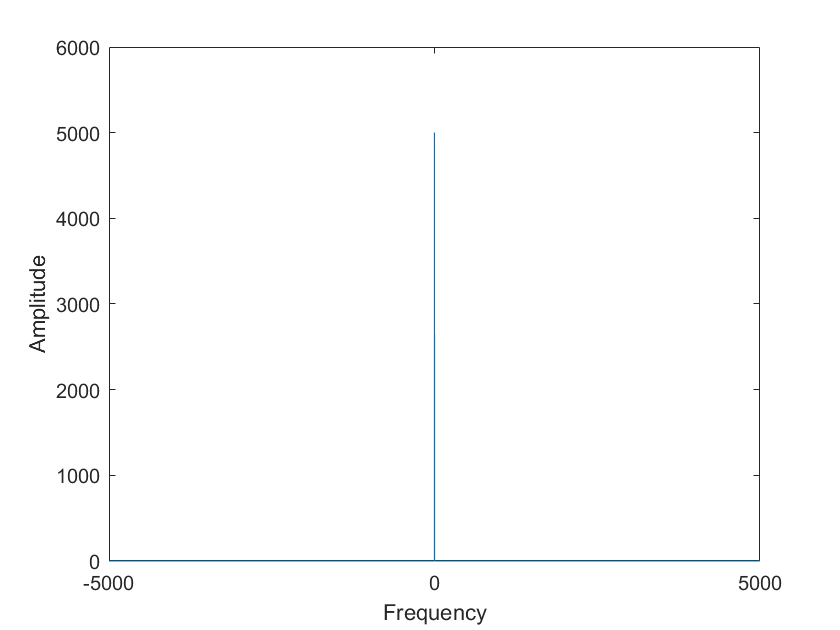

plotF(message, fs);

调制

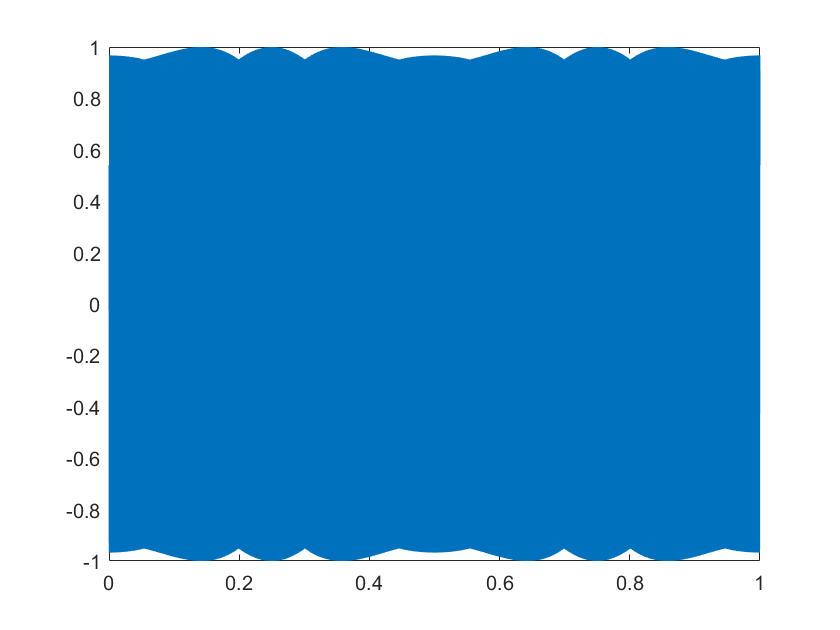

Kp = 1;
Ac = 1;
modulated = Ac * cos(2*pi*1000*t + Kp*message);
plot(t, modulated);

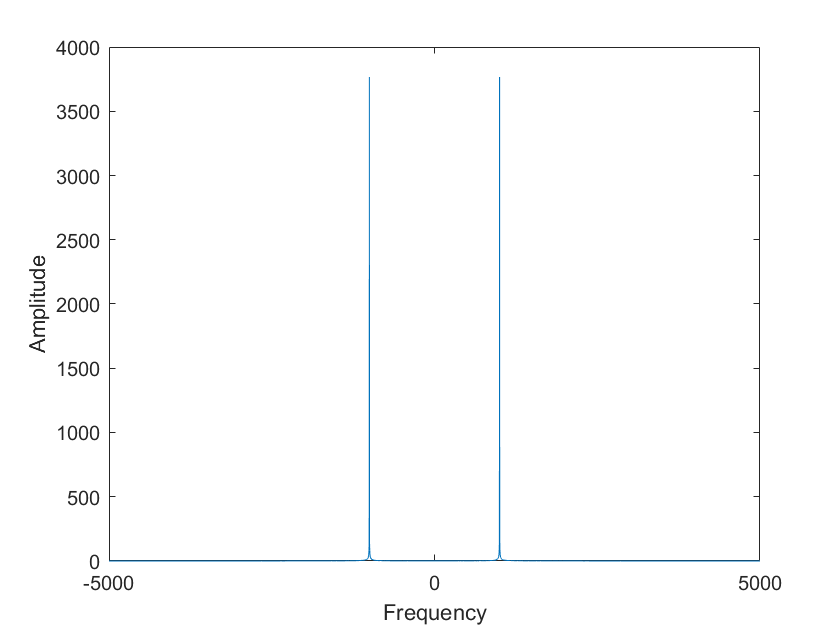

plotF(modulated, fs);

信道

sig_in_channel = modulated;

解调

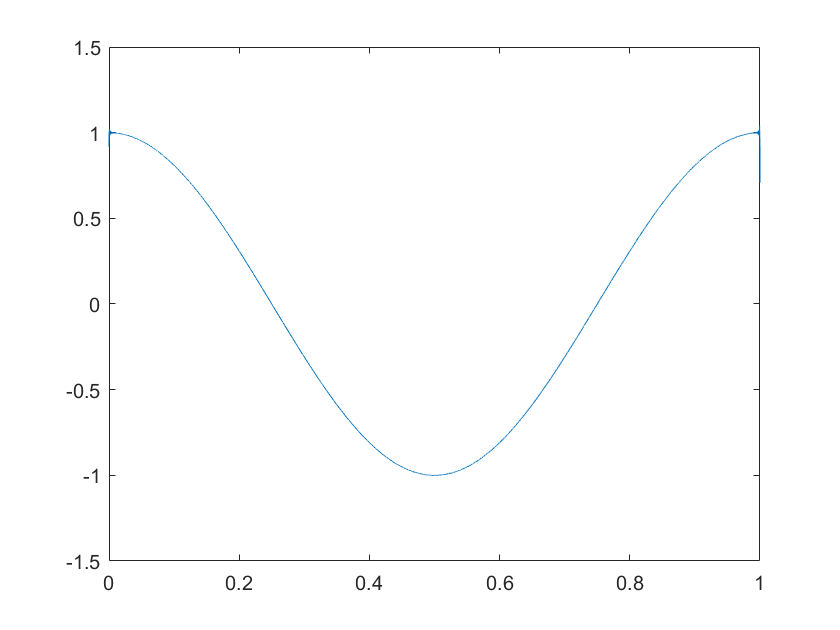

analytic_modulated = hilbert(sig_in_channel);
out = unwrap(angle(analytic_modulated)) - 2*pi*1000*t;
plot(t, out);

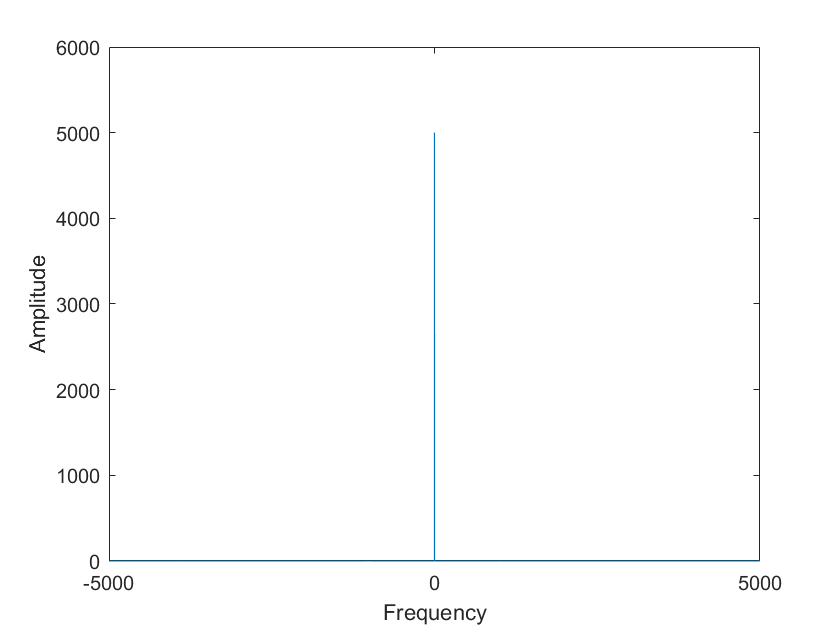

plotF(out, fs);